**Exercici 3. **

Es pretén dissenyar un algoritme simple d’auto-enfoc. La idea és comparar varies imatges d’una mateixa escena adquirides movent l’enfoc de la càmera (que se suposa motoritzat).  Per exemple en la següent seqüència d’imatges (fig1) es pot veure com al anar variant la distància focal de la lent s’obtenen imatges amb enfoc en diferents profunditats. Les imatges les trobareu annexes a aquest document.

 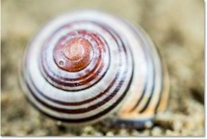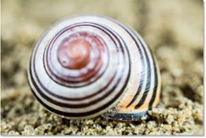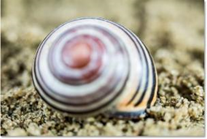

Fig 1. D’esquerra a dreta: enfoc molt proper, a mitja distància i passat l’objecte.  

Com es pot observar, quant una part de la imatge està desenfocada presenta els contorns suavitzats. Llavors, la idea bàsica del nostre senzill sistema d’auto-enfoc és que la imatge que contingui més “derivada” en la seva part central és que estarà més ben enfocada. 

    1. El primer que farem és llegir les imatges i les convertim a nivell de grisos (rgb2gray).

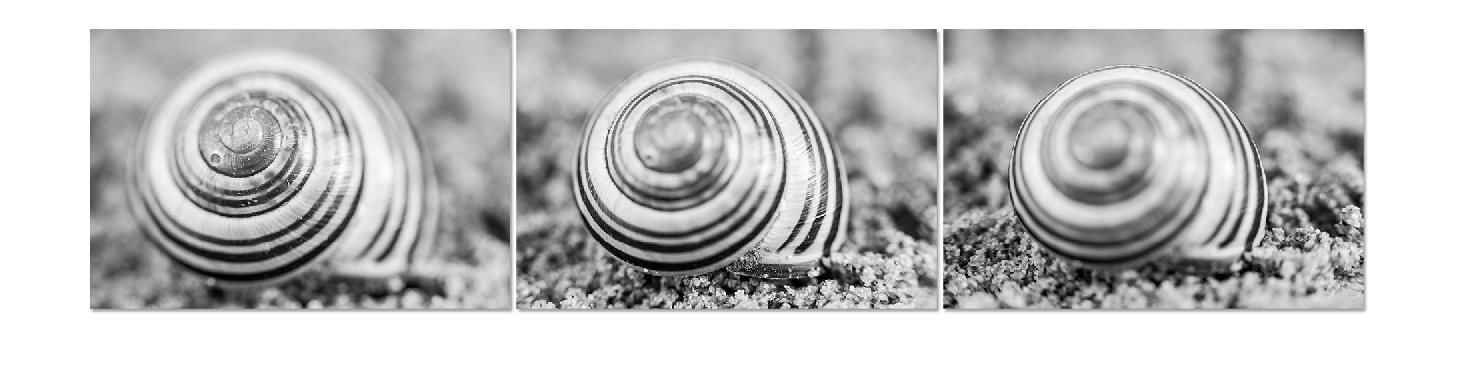

img1 = imread("_61A5845.jpg");
img2 = imread("_61A5855.jpg");
img3 = imread("_61A5861.jpg");

img1 = rgb2gray(img1);
img2 = rgb2gray(img2);
img3 = rgb2gray(img3);

montage({img1, img2, img3}, 'Size', [1 3]);

    2. Passarem un filtre derivatiu (*sobel* o similar) per detectar els contorns verticals Sy i horitzontals Sx. Vigileu el tipus de la imatge doncs no us trunqui els valors negatius o valors més grans que 255.

    3. Com que en aquesta aplicació és indiferent si el contorn és positiu o negatiu, vertical o horitzontal, calcularem el valor absolut de Sx i Sy, i els sumarem.

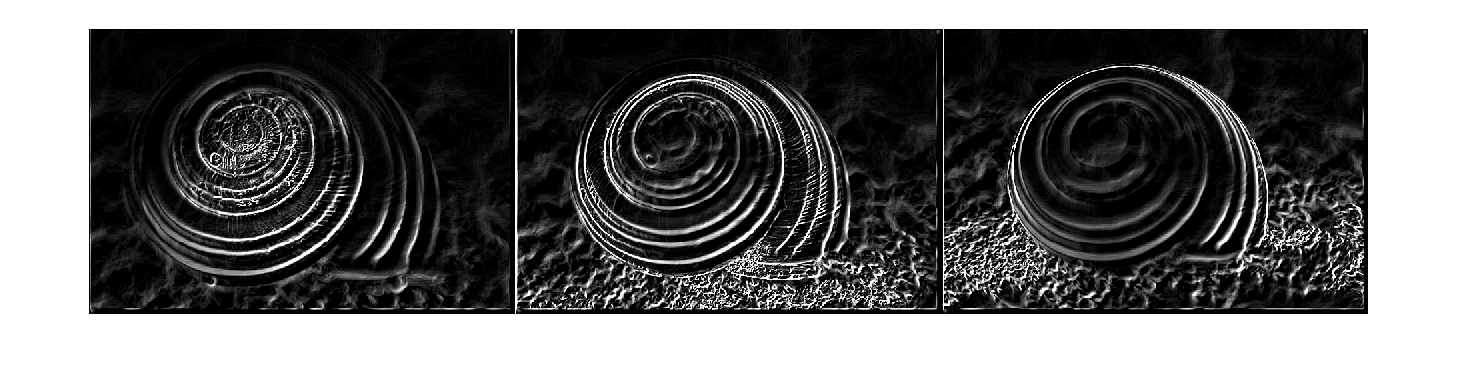

fimg1 = filtre_der(img1);
fimg2 = filtre_der(img2);
fimg3 = filtre_der(img3);
montage({fimg1, fimg2, fimg3}, 'Size', [1 3])

% fimg1 = filtre_der2(img1);
% fimg2 = filtre_der2(img2);
% fimg3 = filtre_der2(img3);
% montage({fimg1, fimg2, fimg3},'Size', [1 3])

    4. Calcularem un valor ***m***de mèrit de l’enfoc i compararem els resultats de les tres imatges. La imatge que proporcioni un valor ***m*** més alt és la que es considerarà de millor enfoc. La funció que calcula el valor ***m*** queda a la vostre elecció, però seria interessant que ponderes amb major pes els píxels centrals de la imatge que els de la perifèria.  

% Obtenim les mides de les imatges (numero de pixels d'altura i d'ample)
m1 = get_m2(fimg1)

m1 = int32
2147483647

m2 = get_m2(fimg2)

m2 = int32
2147483647

m3 = get_m2(fimg3)

m3 = int32
2147483647

function m = get_m(img)
mida = size(img);
if mida(1) > mida(2)
   max_dist = mida(1) / 2;
else
   max_dist = mida(2) / 2;
end

x0 = mida(1) / 2;
y0 = mida(2) / 2;

m = 0;
for x1 = 1:mida(1)
    for y1 = 1:mida(2)
        dist = sqrt((x1 - x0)^2+(y1 - y0)^2);
        m = m + int32(img(x1, y1)) * (1 - dist/max_dist);
    end
end
end



function m = get_m2(img)
mida = size(img);
m = 0;
for i = 1:mida(1)
    for j = 1:mida(2)
        if i < (mida(1) / 2) && j < (mida(2) /2 )
            m = m + int32(img(i, j)) * (i + j);
        elseif i < (mida(1) / 2) && j >= (mida(2) /2 )
            m = m + int32(img(i, j)) * (i + mida(2) - j);
        elseif i >= (mida(1) / 2) && j < (mida(2) /2 )
            m = m + int32(img(i, j)) * (mida(1) - i + j);
        else 
            m = m + int32(img(i, j)) * (mida(1) - i + mida(2) - j);
        end
    end
end
end

function fimg = filtre_der2(img)
Sx = edge(img, 'sobel', 'vertical');
Sy = edge(img, 'sobel', 'horizontal');

fimg = abs(Sx) + abs(Sy);

sup = sum(sum(fimg < 0));
inf = sum(sum(fimg > 255));
if sup > 0 || inf > 0
    error("Valores negativos o mayores a 255");
end
end

function fimg = filtre_der(img)
h = fspecial('sobel');
Sx = imfilter(img, h);
Sy = imfilter(img, h');
fimg = imadd(Sx, Sy);

sup = sum(sum(fimg < 0));
inf = sum(sum(fimg > 255));
if sup > 0 || inf > 0
    error("Valores negativos o mayores a 255");
end
end